# ELEC 460 Assignment 3

Textbook Questions from Ogata B-3-4, B-3-6, B-3-7, B-3-15, B-3-19 from the textbook.

Pulse transfer function relates Z-transform of the output at the sampling instants to the Z- transform of the sampled input.

## B-3-4

Consider a transfer function system


$$ X(s)=\frac{s+3}{(s+1)(s+2)}$$


Obtain the pulse transfer function by two different methods

syms s z
B34Xs = (s+3)/((s+1)*(s+2))

$$B34Xs = \frac{s+3}{\left(s+1\right)\,\left(s+2\right)}$$

% First answer, ignore
% B34XzA1 = subs(B34Xs ,s,z)
% First answer, get the CTS function and convert that
% to the Z-domain,
XsTemp = ilaplace(B34Xs)

$$XsTemp = 2\,{\mathrm{e}}^{-t}-{\mathrm{e}}^{-2\,t}$$

B34XzA2 = ztrans(XsTemp)

$$B34XzA2 = \frac{2\,z}{z-{\mathrm{e}}^{-1}}-\frac{z}{z-{\mathrm{e}}^{-2}}$$


% Second Answer, convert from laplace domain to z domain using tables
% will need to use partial fractions
Xs2 = partfrac(B34Xs)

$$Xs2 = \frac{2}{s+1}-\frac{1}{s+2}$$

% Using the tables


$$\mathcal{Z} \left\{\frac{1}{s+a} \right\} \rightarrow \frac{1}{1-e^{-at}z^{-1}} $$


## B-3-6

Obtain the z transform of


$$X(s)=\frac{1-e^{-Ts}}{s}\frac{1}{(s+a)^2}$$


## B-3-7

Consider the difference equation system


$$ y(k+1)+0.5y(k)=x(k)$$


where y(0)=0. Obtain the response y(k) when the input x(k) is a unit-step sequence. Also, obtain the MATLAB Solution.

## B-3-15

Obtain the closed-loop pulse transfer function of the system shown in the figure below.

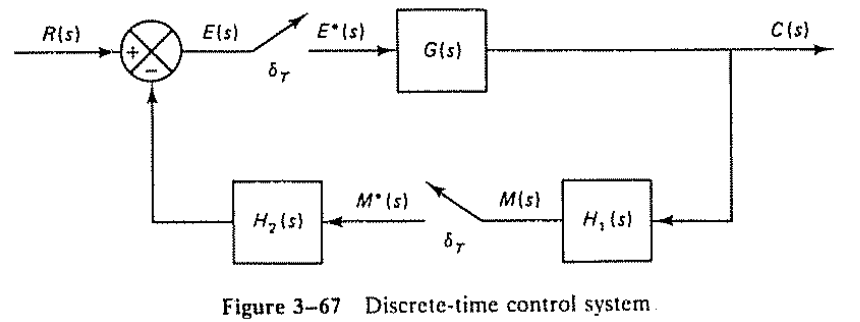

## B-3-17